# ANALYSIS OF SPONTANEOUS ACTIVITY IN SMH 2P

Data obtained by Percival D'Gama at 5dpf. HuC:h2B-GCamp6s smh controls (heterozygous and wt) and smh (homozygous) mutants

Codes updated July 2024 during revision process

See readME file for more information about steps performed before this analysis

Codes used to plot Figure3 panel B-C

See Supplementary Figure for DFF accross all samples, spontaneous activity was only measured from circa 2min to before the first light stimulus.

%%Set path to where your codes are
addpath(genpath('X:\Nathalie\data\github\DGama_et_al_CR_2024'))

## STEP0: enter some parameters

Enter the folder where the data are

cfg.path_data='X:\Manuscripts\Dgama etal 2024 smh\data\Figure 3\Panel B-C\';
% make a path to save Analysed data
mkdir([cfg.path_data 'Analysed' filesep])

Give a name to the brain regions, order given below

cfg.brainRegion=char('telencephalon','TeO/thalamus','Hindbrain', 'Habenula');
cfg

cfg = struct with fields:
      threshold: 4
     percentile: 8
        binSize: 5
         valueA: 50
         valueB: 10
       Mutcolor: 'm'
           type: 'probability'
      path_data: 'X:\Manuscripts\Dgama etal 2024 smh\data\Figure 3\Panel B-C\'
    brainRegion: [4×13 char]


## **STEP1: CALCULATE BASELINE AND RESAMPLE THE DATA**

**THIS STEP ONLY NEED TO BE DONE ONCE!!!!!**

**Uncomment if you need to perform this step!**

LoadF0resample,  does

- only select baseline period. Selected frames 460-2304, circa min 2 to a bit before the first light stimulus, this allows to eliminate possible artefact due to the laser turning on.

- DFF calculation according to Sumbre code (based on 8% percentile). Use a Decay of F0cfg.tauDecay=2;

- Perform clustering on the entire dataset (using Laetitia kmeans clustering code and 5 clusters)

- Resample the data to 1fps, using MATLAB resample function. This is better than smooth.

- Combine the output of all the fishes fromt he same experiment into a single folder

% % Enter the path where the data is. You can copy all of your path below but
% % it is very important that you also copy the cd(path) and the name of the
% % function LoadF0resample as shown in the example below than you can run
% % the whole file.
% 
% path='X:\Percival\2photon data\2022_04_03\20220403_17_56_41_20220403volsmhmutF02\Aligned\celldetection_celldetectionpercy2detectiontimepoint\'
% cd(path)
% LoadF0resample(path)
% 
% path='X:\Percival\2photon data\2022_05_27\20220527_13_17_44_20220527volsmhmutF03\Aligned\celldetection_celldetectionpercy2detectiontimepoint\'
% cd(path)
% LoadF0resample(path)
% 
% % ONCE ALL THE FILES ARE ANALYSED, YOU MUST MOVE ALL THE FILES FROM ONE EXPERIMENT TO ONE DEDICATED
% % FOLDER, SHOULD CONTAIN ALL CTRL AND ALL MUTANT. THIS FOLDER WILL BE USED
% % FOR THE NEXT STEPS

## STEP2: LOAD ALL THE DATA OF ONE EXPERIMENT INTO ONE CELL ARRAY AND CLUSTER THE DATA BY BRAIN REGION

**THIS STEP ONLY NEED TO BE DONE ONCE!!!!!**

**Uncomment if you need to perform this step!**

The code will pull all the DFF and the xyzb into one dataset.

Code nj_ClusterPerBrainRegion_Allfish

- the code makes a clustering per brain region (using Laetitia kmeans clustering code and 5 clusters) per fish

- the code combines all controls and all mutants into one ctrl and one mutant cell array. **(For it to work the ctrl files should include ctrl in the filename and mutants files should contain mut in the filename)**

%[ctrlFish,mutFish]=nj_ClusterPerBrainRegion_Allfish(cfg.path_data);

## STEP3: CALCULATE BRAIN ACTIVITY PER BRAIN REGION

Use code nj_plotCellsThreshold

- you need to load the cell arrays containing all controls and all mutants (end step 2)

load('X:\Manuscripts\Dgama etal 2024 smh\data\Figure 3\Panel B-C\data_spontaneous.mat')

- The code calculates activity based on a threshold, best was 4x8th percentile (see optimization steps on github for more information)

- Set the parameters

close all, clear Nctrl Nmut edges

% set some parameters for thresholding the data--------------------------
cfg.threshold=4;
cfg.percentile=8; %8th percentile based on Romano et al, Plos computational biology, 2017 https://doi.org/10.1371/journal.pcbi.1005526
cfg.binSize=5;
% identify % of active cells (above threshold valueA) and inactive cells (below threshold valueB) 
cfg.valueA=50; 
cfg.valueB=10;
% add extra information into cfg


- Enter the color you want for your mutant display, 'm'= magenta, 'c'=cyan

cfg.Mutcolor='m'; %enter the color you want for your mutantd display, 'm'= magenta, 'c'=cyan

- The code plots a histogram with the %time the neuron is more active than a threshold (x is %time and Y is %cells) per brain region

- The code plots also a scatter with the % of cells that are very active (active more than 50% of the time) or inactive (active less than 10% of the time) per brain region

- Statistical values are ranksum

choose if cumulative distribution or probability

cfg.type='probability'%  'probability' or 'cdf'
% 'cdf' does cumulative distribution, 'probability' does a histogram

plot  histograms

nj_plotCellsThreshold(ctrlFish,mutFish, cfg)

cfg = struct with fields:
      threshold: 4
     percentile: 8
        binSize: 5
         valueA: 50
         valueB: 10
       Mutcolor: 'm'
           type: 'probability'
      path_data: 'X:\Manuscripts\Dgama etal 2024 smh\data\Figure 3\Panel B-C\'
    brainRegion: [4×13 char]


shadded error bars are SEM

## STEP4: CORRELATION VERSUS DISTANCE FOR ALL BRAIN REGIONS 

set some parameters for the display

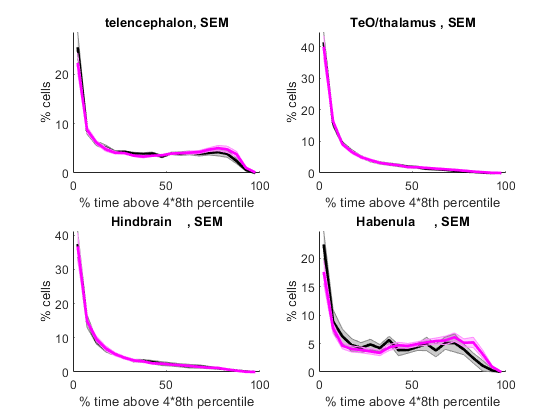

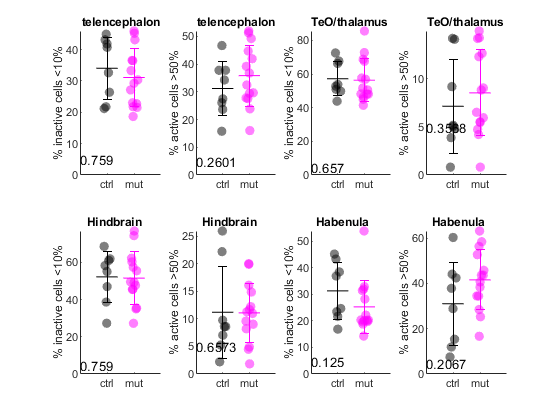

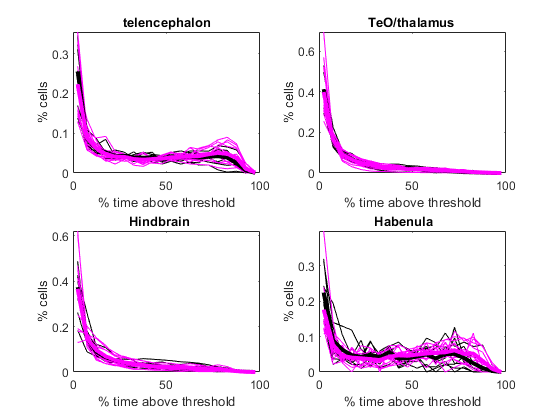

cfg.binSize=20;% this value is in um and decide the bin size of the histogram

- The code plot a binscatter for each fish and brain region

- The code plots a histogram with the mean correlation versus distance per brain region

- The code plots also a scatter with the average positive or negative correlation for distance shorter than 60microns per brain region

- Statistical values are ranksum

plot the correlation versus distance for each individual fish and the average for all samples

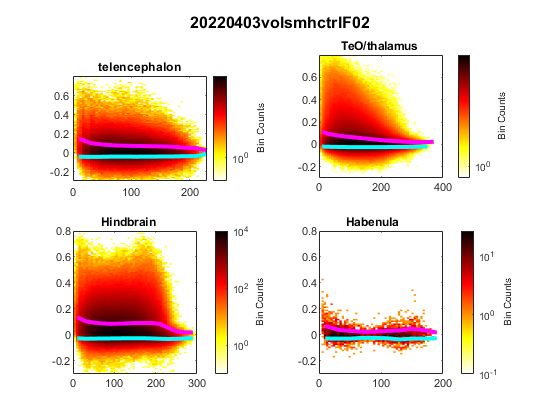

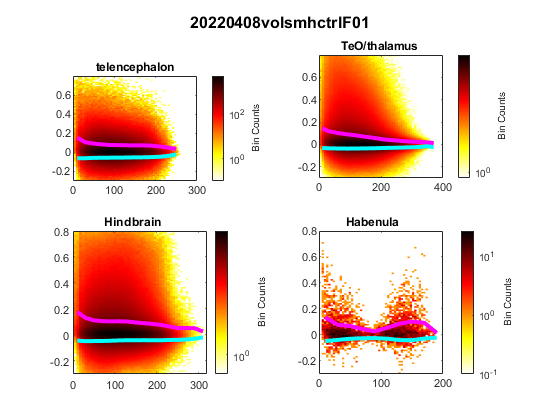

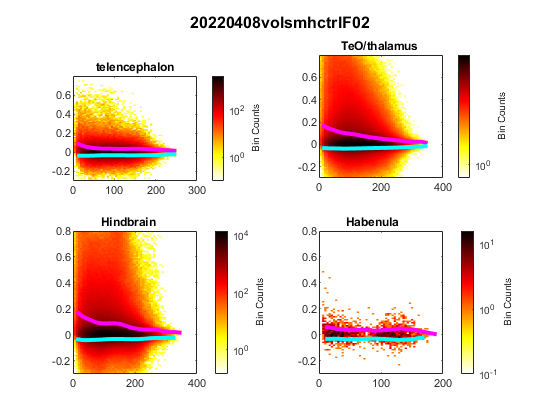

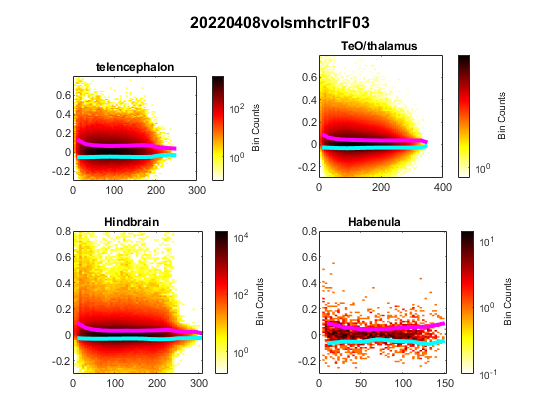

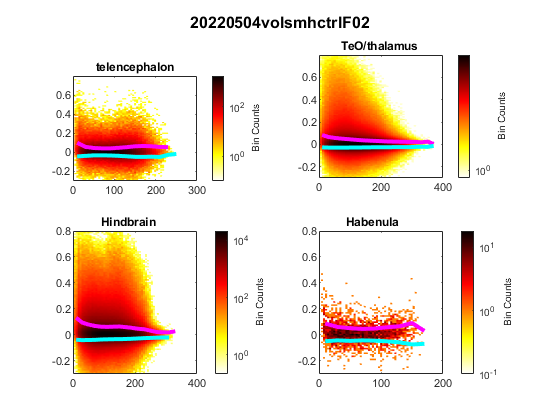

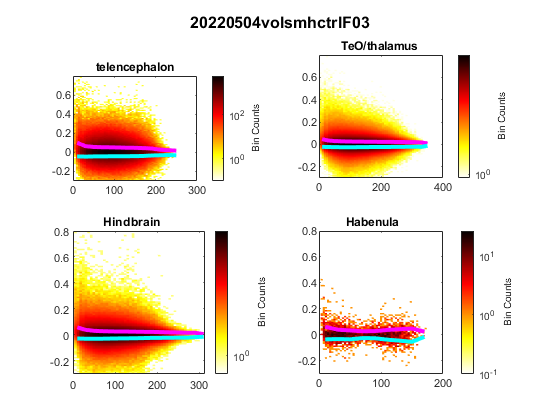

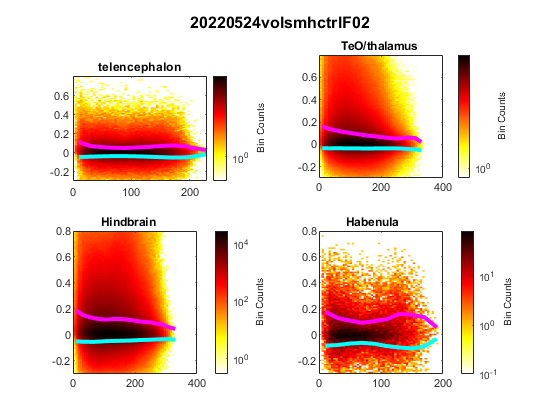

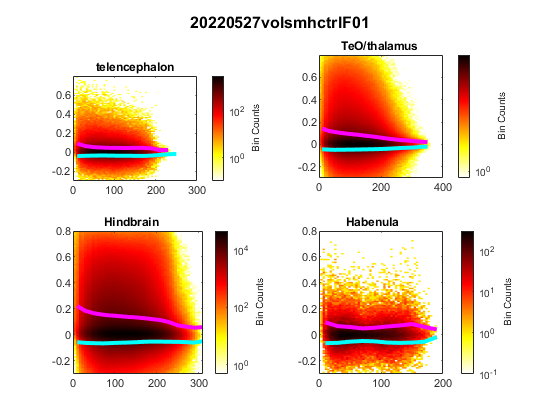

nj_correlationVSdistance_v2(ctrlFish, mutFish, cfg)

shadded error bars are SEM